# ECE 203 Lab Assignment 3: Multi-Path Interferance

### ### Carson Batchelor ###

# Live Script containing skeleton code for Lab Assignment 3 created by Talha Sultan, 02/2021 #

## Prepare workspace

close all
clear

% Complete the following lines of Code 
% Uncomment to run

dt = 1000; % meters
dxr = 80;  % meters
dyr = 600; % meters
c = 3 * 10^8;   % speed of radio signal propagation meters/sec.

## Part (a): Direct path propagation delay t1 from vehicle to Transmitter

% Complete the following lines of Code 
% Write dir_delay function and then uncomment to call function

xv = 0;
t1 = dir_delay(xv, dt, c);

t1

t1 = 3.3333e-06

% Uncomment to run and check function output for xv = 0
disp('Part (a) Direct Path Delay')

Part (a) Direct Path Delay


disp(['t1(0) = ' num2str(dir_delay(0,dt,c)) ' sec'])

t1(0) = 3.3333e-06 sec


## Part (b): Reflective path delay where reflector is at (dxr, dyr)

% Complete the following lines of Code 
% Write dir_delay function and then uncomment to call function

xv = 0;
t2 = refl_delay(xv,dt,c,dxr,dyr)

t2 = 3.3774e-06


% Uncomment to run and check function output for xv = 0
disp('Part (b) Reflective Path Delay')

Part (b) Reflective Path Delay


disp(['t2(0) = ' num2str(refl_delay(0,dt,c,dxr,dyr))])

t2(0) = 3.3774e-06


## Part (c): Received Signal at the Vehicle (Sum of 2 Signals) 

% Complete the following lines of Code 
% Uncomment to run

% Part 1: Predict Amplitude and Phase of rv using Phasor Addition Rule
f = 100*1e6;
% Amplitude and Phase Shift of Sinusoid 1: Direct Path from t1(xv)
A1 = 1; phi1  = -2*pi*f*t1;

% Amplitude and Phase Shift of Sinusoid 2: Direct Path from t2(xv)
A2 = 1; phi2  = -2*pi*f*t2+pi;

% Use Phasor Addition Rule to calculate A, phi for rv (use pen and paper)

% Hint: Check your work using AddPhasors.m function you wrote down
% previously

amps = ones(2,1);
phases = [phi1; phi2];

[A,phi] = AddPhasors(amps, phases)

A = 1.9214

phi = -1.8131

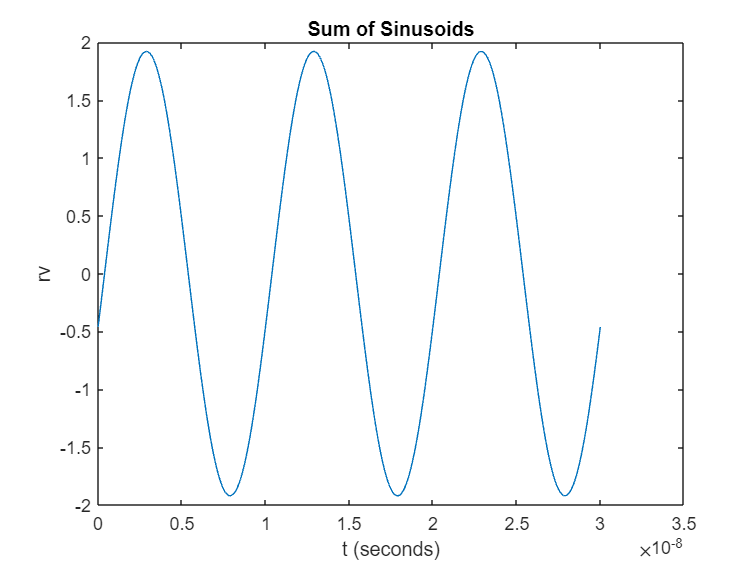

% Part 2: Plot total signal rv vs t (for fixed xv)

% Enter Inputs
f = 100*1e6;  % Hz
T = 1/f;  % Period (sec)
t = 0 : T/100 : 3*T;  % time samples for three cycles, 100 points per cycle

% vehicle position
xv = 0; 
dt = 1000; 
dxr = 80;  
dyr = 600; 
c = 3 * 10^8;

% Call function dir_delay to compute delay of direct path
t1 = dir_delay(xv, dt, c);  

% Generate sinusoid signal from the direct signal
A = 1;
Omega = 2*pi*f;

rdir =  A * cos(Omega * t + phi1);

% Call function refl_delay to compute delay of relected path
t2 = refl_delay(xv,dt,c,dxr,dyr); 

% Generate sinusoid signal from the reflected signal
rref = A * cos(Omega * t + phi2);

% Compute Sum of Sinusoids 
rv = rdir + rref;
rv;
% Plot rv vs t when xv = 0;
figure; 
plot(t, rv)
hold on; 
title('Sum of Sinusoids')
xlabel('t (seconds)')
ylabel('rv')
hold off


% Hint: Another way to solve this is to write down the closed-form
% expression for rv using the Phasor Addition Rule. Does your plot match
% this expression?

## Part (d) received signal strength versus xv

% Complete the following lines of Code 
% Uncomment to run

% Enter Inputs
lambda = c/f; % meters
xv = 0: lambda/100 :300 ; 
N = length(xv); % # of points to use
% Compute Amplitude of rv for different xv

t1 = dir_delay(xv,dt,c);
t2 = refl_delay(xv,dt,c,dxr,dyr);

A1 = 1; phi1  = -2*pi*f*t1;
A2 = 1; phi2  = -2*pi*f*t2+pi;

amps = ones(2,N);
phases = [phi1; phi2];

[A_xv, phi_xv] = AddPhasors(amps,phases);

A_xv =     1.9214    1.9191    1.9167    1.9143    1.9119    1.9095    1.9070    1.9045    1.9019    1.8993    1.8967    1.8941    1.8914    1.8887    1.8859    1.8832    1.8804    1.8775    1.8747    1.8718    1.8688    1.8659    1.8629    1.8598    1.8568    1.8537    1.8506    1.8474    1.8442    1.8410    1.8378    1.8345    1.8312    1.8278    1.8245    1.8211    1.8176    1.8142    1.8107    1.8071    1.8036    1.8000    1.7964    1.7928    1.7891    1.7854    1.7816    1.7779    1.7741    1.7703


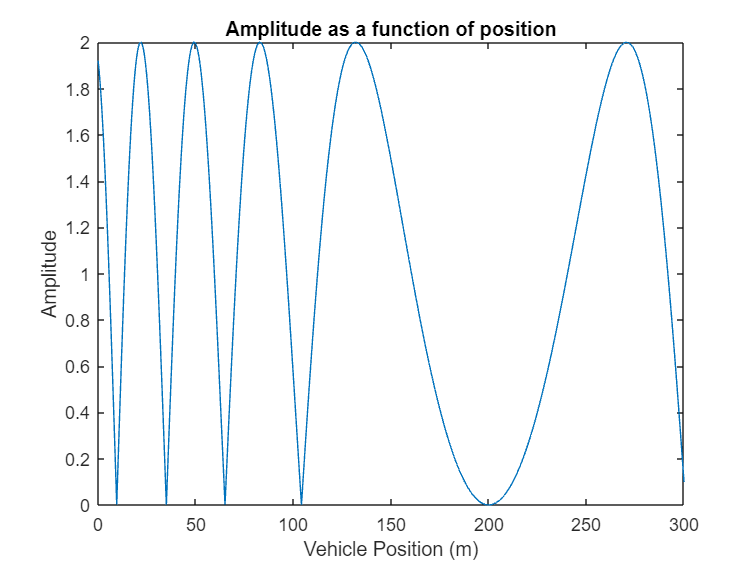

% Plot Amp of rv vs xv
figure;
plot(xv, A_xv)
xlabel('Vehicle Position (m)');
ylabel('Amplitude');
title('Amplitude as a function of position')

% Find Minimum Amplitude
min(A_xv)

ans = 6.5824e-08

amps = [3,5];
phases = [2*pi/9; 0];

[A,phi] = AddPhasors(amps, phases)

A = 7.5486

phi = 0.2583



% Phaser Addition
x1 = 3*exp(1j*(pi/4))

x1 = 2.1213 + 2.1213i

x2 = 4*exp(1j*(3*pi/4))

x2 = -2.8284 + 2.8284i

X = x1+x2

X = -0.7071 + 4.9497i

abs(X)

ans = 5

angle(X)

ans = 1.7127


















x1 = 6*exp(1j*(pi/2))

x1 = 0.0000 + 6.0000i

x2 = 8*exp(1j*(pi))

x2 = -8.0000 + 0.0000i

X = x1+x2

X = -8.0000 + 6.0000i

abs(X)

ans = 10

angle(X)

ans = 2.4981



p3 = 16*exp(-1j*(pi/3))

p3 = 8.0000 - 13.8564i


angle(p3)

ans = -1.0472